% Result #4- Two methods for detecting the freezing periodResult #4- Two methods for detecting the freezing period
% We believe that the Median value can show the start of freezing period pretty well but it overestimates the end of freezing period. 

% On the other hand absolute minimum discharge normally shows the unset of melting and can be a measure for detecting the end of freezing period.
% 
% For this result we can combine both approaches to see how each method affects the results
% 
% We already have the results from Median approach (the results are the duration of freezing period in each year) and it will be compared with the results from combination of median (for starting point) and absolute minimum (ending point of freezing)
% 

clc;
clear all;
clearvars;

stations={'Kukko'};

    clearvars -except jj stations
    filename = 'C:\Abolfazl\Research\PhD\cases 3mar2021\Kukko2.xlsx';
    [NUM,TXT,RAW] = xlsread(filename,stations{1});
    tot_per= floor(size(NUM,1)/365); %total periods in one station
    intervals=[1];

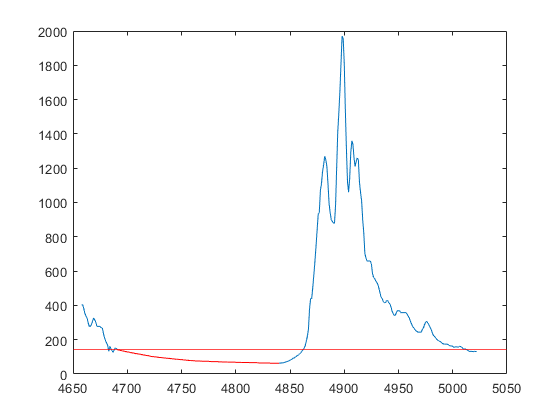

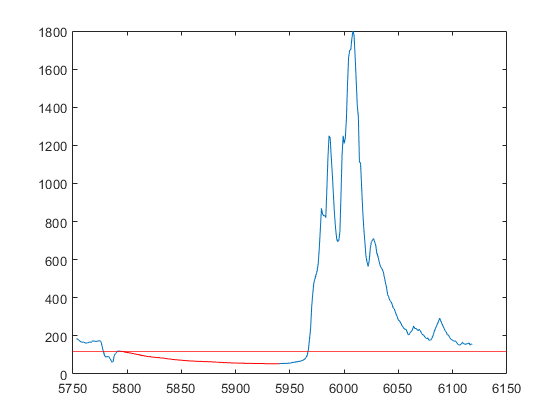

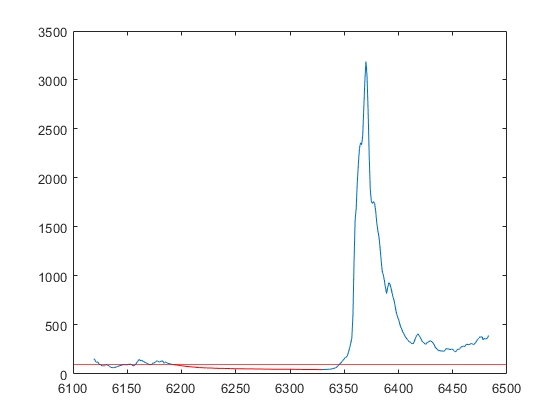

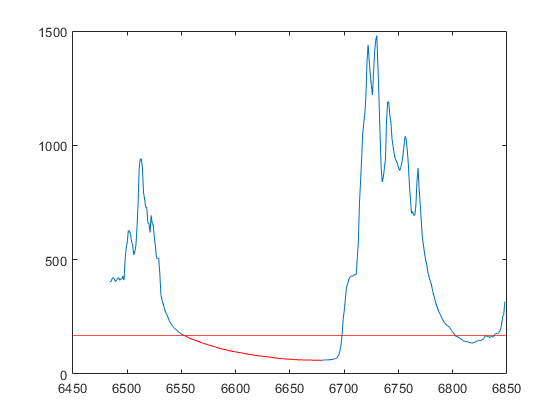

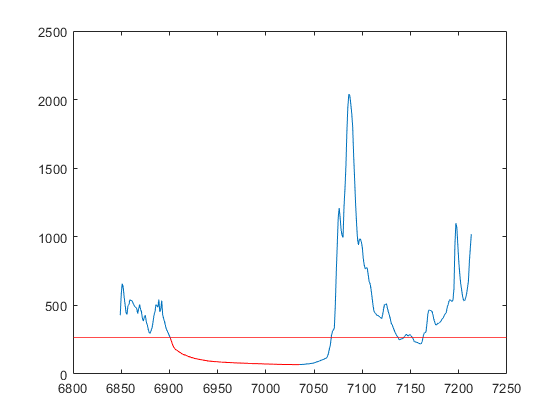

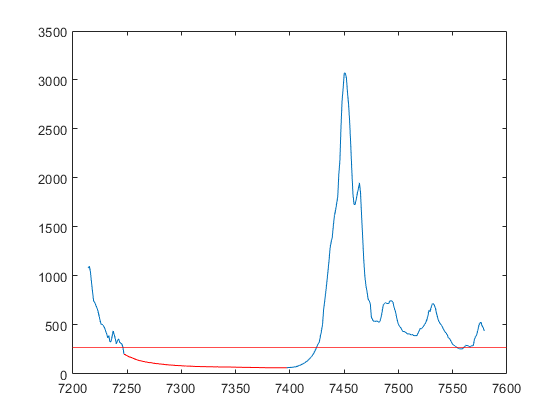

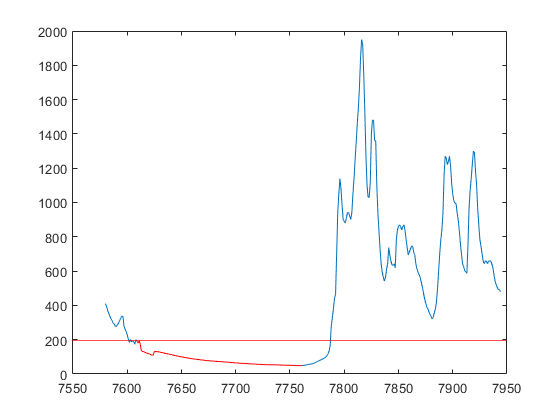

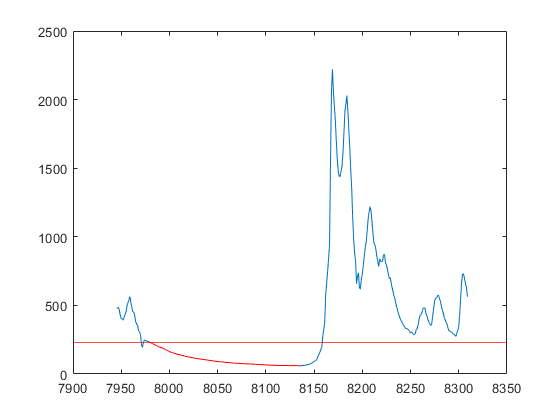

    for j=1:size(intervals,2)
        k=1;
        for jjj=1:tot_per
            clear seq L_values seq_modified2 seq_modified seq_temp seq_temp2 A_tmp m2 min_v ind_min_v m3 min_v_row
            A(:,1) = NUM(k:jjj*365,1); 
            A(:,2) = NUM(k:jjj*365,2);

            med = median(A(:,2));
            med=intervals(1,j)*med;
            miane(1:size(A,1),1)=med;

           
            consenums = find(A(:,2)<=med);

            

            consenums=consenums' ;  %  array of consecutive numbers
            consenums(end+1)=2 ;  % adds new endpoint to very end of A so code picks up end of last group of consecutive values
            I_1=find(diff(consenums)~=1);  % finds where sequences of consecutive numbers end
            [m,n]=size(I_1);   % finds dimensions of I_1 i.e. how many sequences of consecutive numbers you have
            startpoint=1;    % sets start index at the first value in your array
            seq=cell(1,n) ; % had to preallocate because without, it only saved last iteration of the for loop below
                       % used n because this array is a row vector
                for i=1:n
                    End_Idx=I_1(i);   %set end index
                    seq{i}=consenums(startpoint:End_Idx);  %finds sequences of consecutive numbers and assigns to cell array
                    startpoint=End_Idx+1;   %update start index for the next consecutive sequence
                end

            [row,col]=size(seq);
        

                    seq_modified2=seq;
                    for i2=1:col
                        L_values(1,i2) = length(seq_modified2{i2});
                    end 
%                 end 
                   
               %two conditions for selecting the IIP one if the max discharge value
               %happens before 100 (example) and next is the highest
               %duration of IIP, if 
            duration = max(L_values); %days if ice influence period
                [max_dis_value,max_ind]=max(A(:,2));
                if max_ind<100
                    for i3=1:col
                        if length(seq_modified2{i3})==duration
                            ind=i3;
                            Ice_begin_1 = min(seq_modified2{ind});
                            Ice_end_1 = max(seq_modified2{ind});
                        end
                    end
                elseif max_ind >= 100
                    for i3=1:col
                        if length(seq_modified2{i3})==duration
                            ind=i3;
                            Ice_begin_1 = min(seq_modified2{ind});
                            Ice_end_1 = max(seq_modified2{ind});
                            if Ice_begin_1>max_ind
                                clear Ice_begin_1 Ice_end_1 row col i2 L_values
                                seq_modified2{i3}=[];
                                [row,col]=size(seq_modified2);
                                for i2=1:col
                                        L_values(1,i2) = length(seq_modified2{i2});
                                end
                                duration = max(L_values);
                                for i3=1:col
                                    if length(seq_modified2{i3})==duration
                                        ind=i3;
                                        Ice_begin_1 = min(seq_modified2{ind});
                                        Ice_end_1 = max(seq_modified2{ind});
                                    end
                                end
                            end
                        end
                    end
                    
                end
%  %%%%%%%%%%%% intorducing abs minimum for the ending point
       %making a temporary A with the freezing period found by median
                A_tmp(:,1)=A(Ice_begin_1:Ice_end_1,1);
                A_tmp(:,2)=A(Ice_begin_1:Ice_end_1,2);
                min_v=min(A_tmp(:,2));
                [ind_min_v, m3]=find(A(Ice_begin_1:Ice_end_1,2)==min_v);
                tmp_min_v_row=max(ind_min_v);
                tmp_date=A_tmp(tmp_min_v_row,1);
                min_v_row=find(A(:,1)==tmp_date);
                Ice_end_1=min_v_row;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

                %calculating the duration of ice influence period
                IIP_Duration(jjj,1)=Ice_end_1-Ice_begin_1+1;
                
                %getting the starting and ending point of the IIP(Ice
                %influence period)
                IIP_stdy(jjj,1)=Ice_begin_1;
                IIP_stdy(jjj,2)=Ice_end_1;
                if jjj>1
                    Ice_begin_1=Ice_begin_1+((jjj-1)*365);
                    Ice_end_1=Ice_end_1+((jjj-1)*365);
                end
                start_freezing=datestr(x2mdate(NUM(Ice_begin_1)));
                stop_freezing=datestr(x2mdate(NUM(Ice_end_1)));
                start_freezing=cellstr(start_freezing);
                stop_freezing=cellstr(stop_freezing);
                IIP_stdate(jjj,1)=start_freezing;
                IIP_stdate(jjj,2)=stop_freezing;
                
                %The first peak after IIP
                %if jjj=1%%%%%%%%%%%%%%%%
                
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%
                if jjj>1
                    [M,I] = max(A((Ice_end_1-((jjj-1)*365))+1:365,2));
                    I_ind=I+(Ice_end_1-((jjj-1)*365));
                    Max_dis(jjj,2)=M;
                    Max_dis(jjj,1)=I_ind;
                    Max_dis(jjj,3)=I_ind-(Ice_end_1-((jjj-1)*365));
                else
                    [M,I] = max(A(Ice_end_1+1:365,2));
                    I_ind=I+Ice_end_1;
                    Max_dis(jjj,2)=M;
                    Max_dis(jjj,1)=I_ind;
                    Max_dis(jjj,3)=I_ind-Ice_end_1;
                end
                
                %
                k=k+365;
                inte={'10','12','14','16','18','20'};
                %temporary saving images to chck time series
                imagename=num2cell(1:85);
                cp={'r','k','c','m','y',[.8 .2 .6]};
                plot(A(:,1),A(:,2)); hold 'on'
                yline(med,'color',cp{j});
                if jjj==1
                    plot(A(Ice_begin_1:Ice_end_1,1),A(Ice_begin_1:Ice_end_1,2),'-r')
                end
                if jjj>1
                    plot(A(Ice_begin_1-((jjj-1)*365):Ice_end_1-((jjj-1)*365),1),A(Ice_begin_1-((jjj-1)*365):Ice_end_1-((jjj-1)*365),2),'-r')
                end
                filename2=num2str(jjj);
                saveas(gcf,filename2,'jpg')
                close
                
             
        end
%         if jj==1 %this means the first station if jj==2 it is the second station
            
            xlswrite('C:\Abolfazl\Research\PhD\cases 3mar2021\Result4\Kukko\startstopdate.xlsx',IIP_stdate,inte{j})
            xlswrite('C:\Abolfazl\Research\PhD\cases 3mar2021\Result4\Kukko\day.xlsx',IIP_stdy,inte{j})
            xlswrite('C:\Abolfazl\Research\PhD\cases 3mar2021\Result4\Kukko\maxdis.xlsx',Max_dis,inte{j})
            
%         end
%          if jj==1
%             
            xlswrite('C:\Abolfazl\Research\PhD\cases 3mar2021\Result4\Kukko\IIP_Duration.xlsx',IIP_Duration,inte{j})
%            
%         end

    end